A = load("MEASUREA.DAT")

A =     1.0000         0         0         0
    2.0000    0.5000   -0.0018    0.0046
    3.0000    1.0000    0.0056    0.0023
    4.0000    0.5000    0.0320   -0.0011
    5.0000         0    0.0744    0.0041
    6.0000         0    0.1134    0.0024
    7.0000         0    0.1375    0.0012
    8.0000   -0.3333    0.1471   -0.0020
    9.0000   -0.6667    0.1396   -0.0065
   10.0000   -1.0000    0.0995   -0.0050


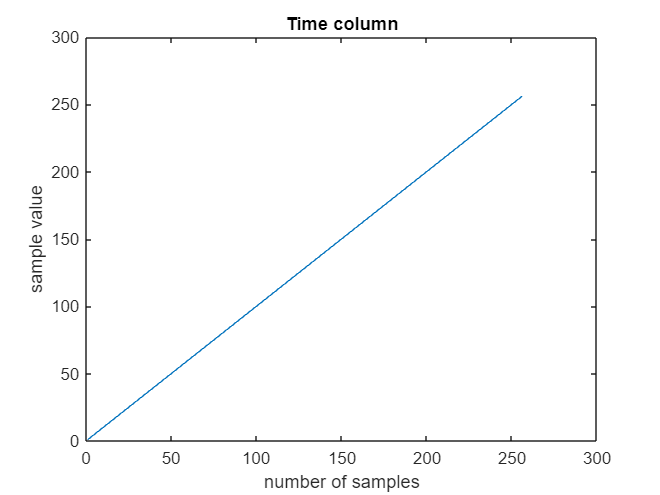

t = A(:,1); % output
u = A(:,2); % input
y = A(:,3); % output


figure
plot(A(:,1))
xlabel("number of samples")
ylabel("sample value")
title("Time column")

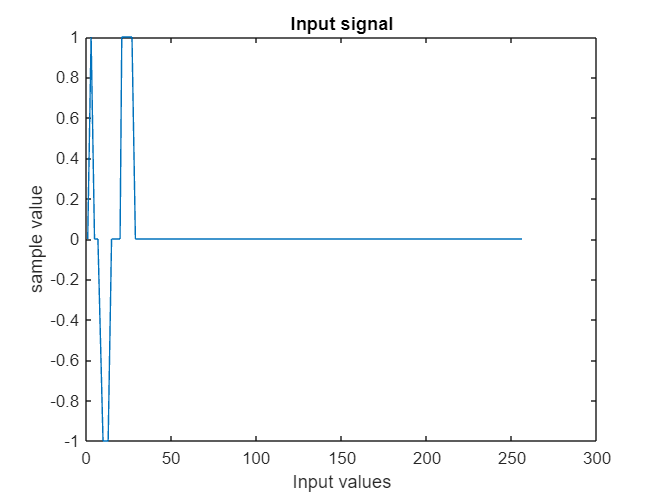



plot(A(:,2))
xlabel("Input values")
ylabel("sample value")
title("Input signal")

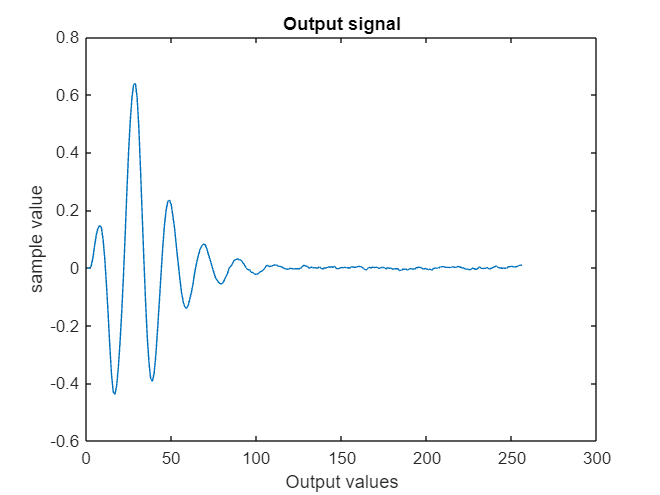


plot(A(:,3))
xlabel("Output values")
ylabel("sample value")
title("Output signal")

N = length(t);
T = t(2,1) - t(1,1);


F = 1 / (N * T);

fmax = 1/(2*T);

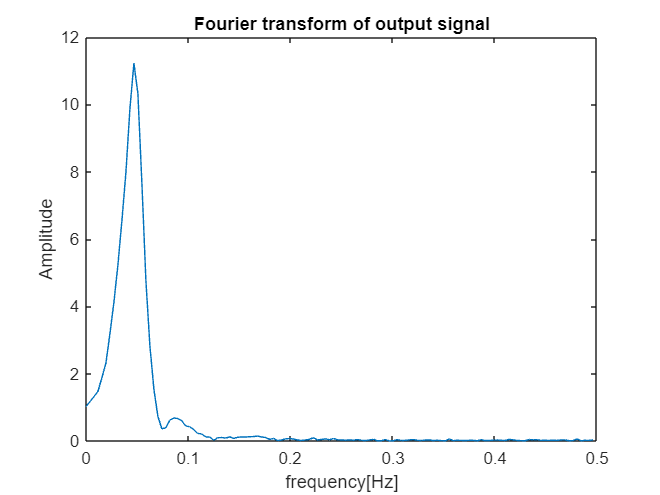

% FFT

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

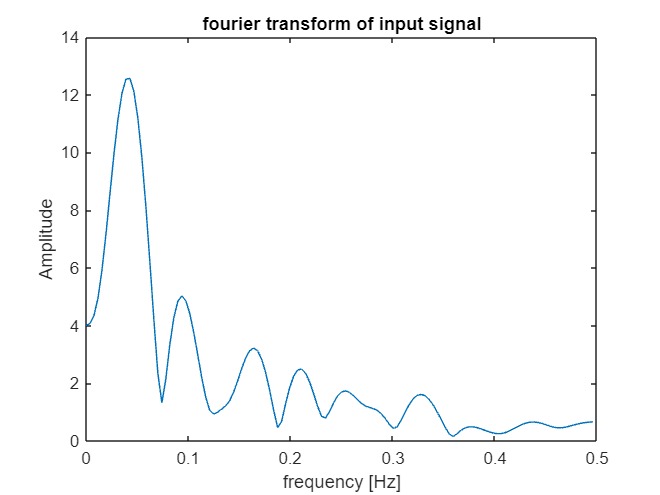

plot(v,abs(FT_input(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

% frequency vektor
v = 0:F:(fmax - F)

v =          0    0.0039    0.0078    0.0117    0.0156    0.0195    0.0234    0.0273    0.0312    0.0352    0.0391    0.0430    0.0469    0.0508    0.0547    0.0586    0.0625    0.0664    0.0703    0.0742    0.0781    0.0820    0.0859    0.0898    0.0938    0.0977    0.1016    0.1055    0.1094    0.1133    0.1172    0.1211    0.1250    0.1289    0.1328    0.1367    0.1406    0.1445    0.1484    0.1523    0.1562    0.1602    0.1641    0.1680    0.1719    0.1758    0.1797    0.1836    0.1875    0.1914


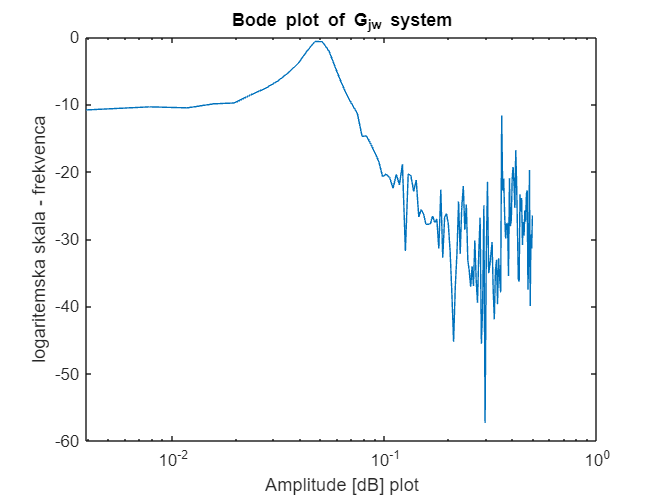

% frequency response


G_jw = FT_output ./ FT_input;

semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Bode plot of G_jw system")
xlabel("Amplitude [dB] plot")
ylabel("logaritemska skala - frekvenca")

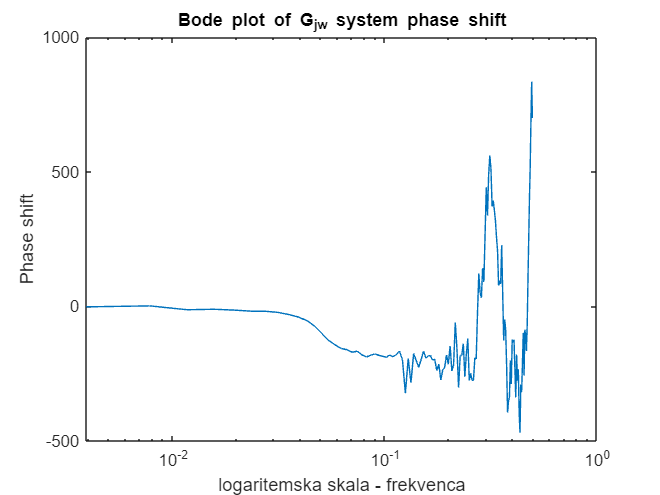



faza = unwrap(angle(G_jw));
semilogx(v,180/pi*(faza(1:end/2)))
title("Bode plot of G_jw system phase shift")
ylabel("Phase shift")
xlabel("logaritemska skala - frekvenca")

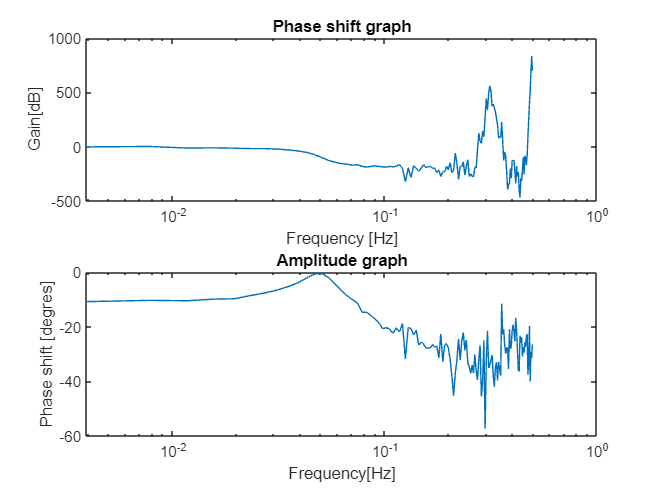


subplot(2,1,1), semilogx(v,180/pi*(faza(1:end/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Phase shift [degres]")

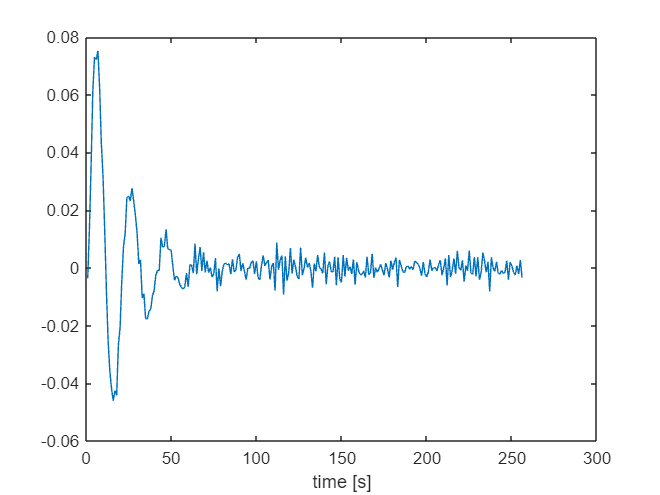

% inverse fourier

g = ifft(G_jw);
figure
plot(g)
xlabel("time [s]")

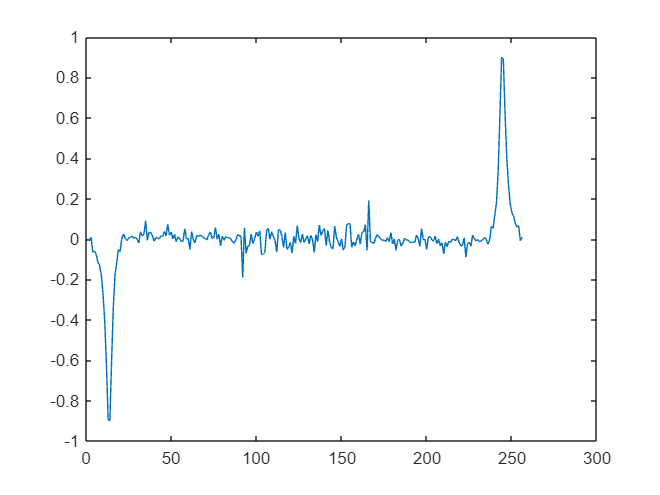

plot(imag(G_jw))

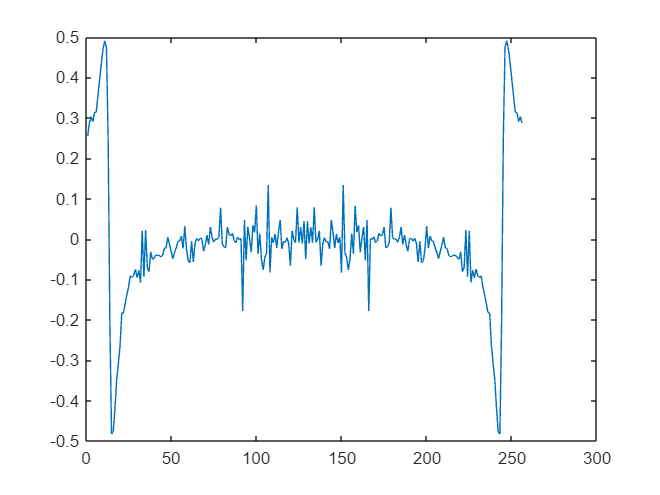

plot(real(G_jw))

n = A(:,4)

n =          0
    0.0046
    0.0023
   -0.0011
    0.0041
    0.0024
    0.0012
   -0.0020
   -0.0065
   -0.0050


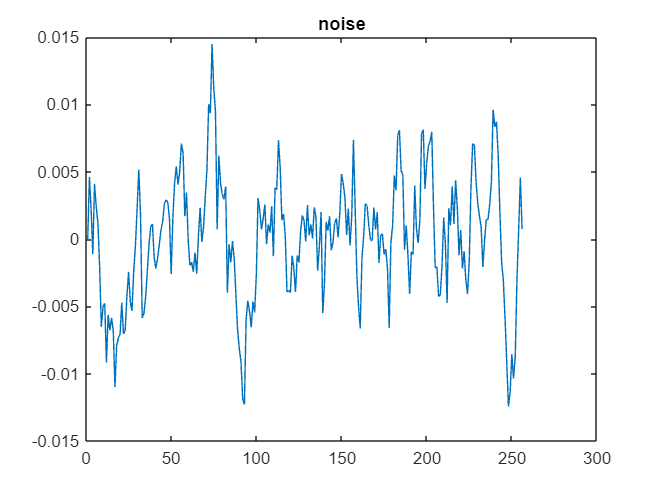

figure
plot(n)
title("noise")


Noise = fft(n);
plot(v,abs(Noise(1:end/2)))
title("fourier transformed noise")

hold on

N0 = 0.3;
N_inf = 0.04;

wg = 0.03;

%Ng = abs(Noise(wg));
approx = N_inf + ((N0 - N_inf)./sqrt(1 + pow2(v/wg)))

approx =     0.2238    0.2197    0.2154    0.2110    0.2066    0.2022    0.1977    0.1932    0.1887    0.1842    0.1797    0.1752    0.1708    0.1664    0.1621    0.1578    0.1536    0.1495    0.1455    0.1415    0.1377    0.1340    0.1303    0.1268    0.1234    0.1201    0.1168    0.1137    0.1107    0.1078    0.1050    0.1023    0.0997    0.0972    0.0948    0.0925    0.0903    0.0881    0.0861    0.0841    0.0822    0.0804    0.0786    0.0770    0.0754    0.0738    0.0724    0.0710    0.0696    0.0683


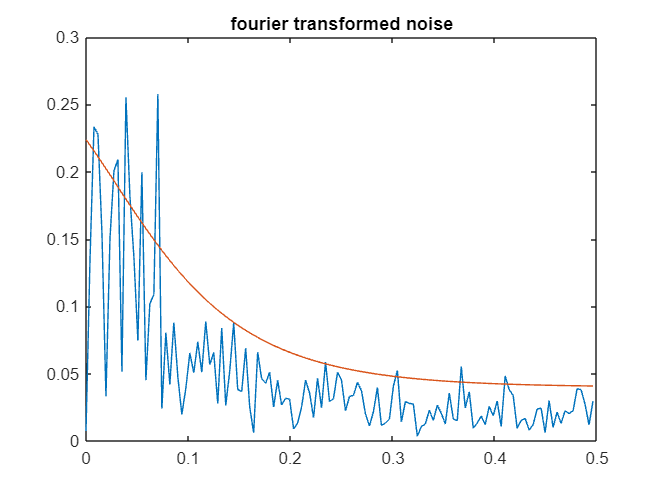

plot(v, approx)

model = @(params) N_inf + ((N0 - N_inf)/sqrt(1 + pow2(params/wg)))

%  nv = [] 
%    for i = 0:0.0035:v(end)
%        nv = [nv,model(i)];
%    end

d_G = (abs(approx))./abs(FT_input(1:end/2))'

d_G =     0.0560    0.0539    0.0495    0.0426    0.0349    0.0282    0.0231    0.0194    0.0169    0.0153    0.0143    0.0139    0.0141    0.0149    0.0165    0.0194    0.0247    0.0355    0.0621    0.1065    0.0639    0.0401    0.0305    0.0262    0.0245    0.0247    0.0265    0.0303    0.0372    0.0491    0.0695    0.0964    0.1069    0.0967    0.0855    0.0759    0.0645    0.0519    0.0412    0.0335    0.0286    0.0257    0.0244    0.0246    0.0266    0.0312    0.0411    0.0662    0.1484    0.1005


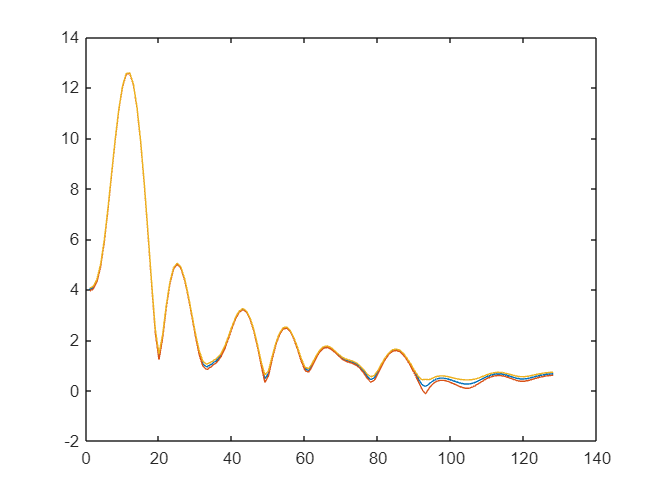


figure
plot(abs(FT_input(1:end/2)))
hold on
plot(abs(FT_input(1:end/2)) - d_G')
plot(abs(FT_input(1:end/2)) + d_G')

## part 2

proces=procesa(u)

proces =          0
         0
    0.0149
    0.0445
    0.0587
    0.0576
    0.0564
    0.0550
    0.0435
    0.0221


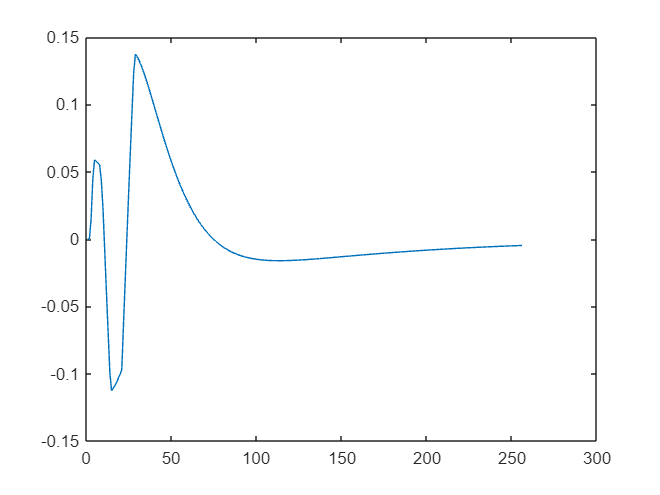

figure
plot(proces)

T = 0.1;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F);

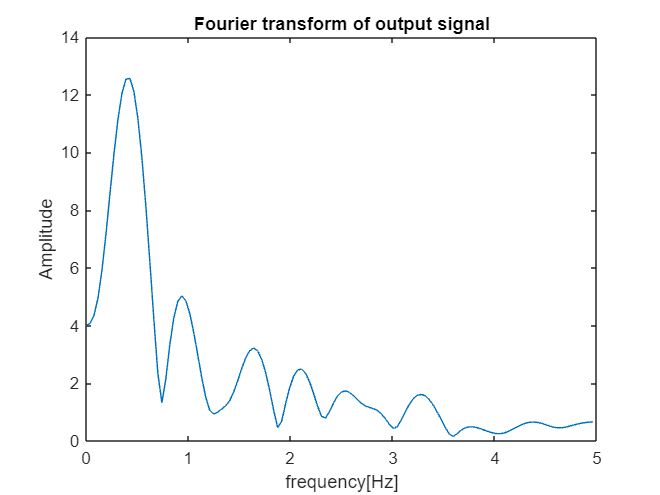

FT_input = fft(u);
FT_proces = fft(proces);

figure;

plot(v,abs(FT_input(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

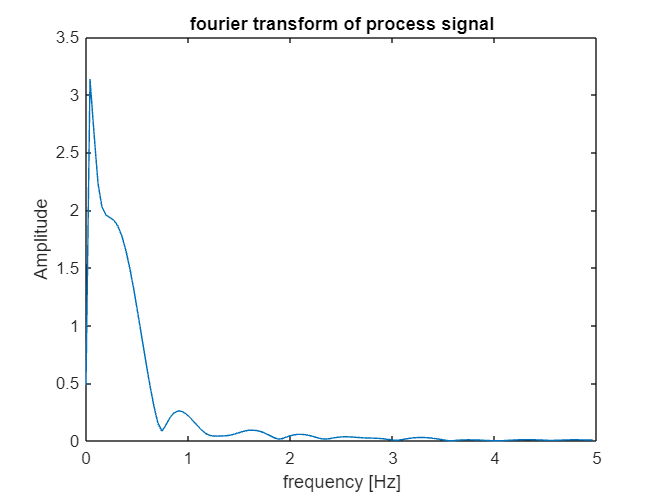


plot(v,abs(FT_proces(1:end/2)))
title("fourier transform of process signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

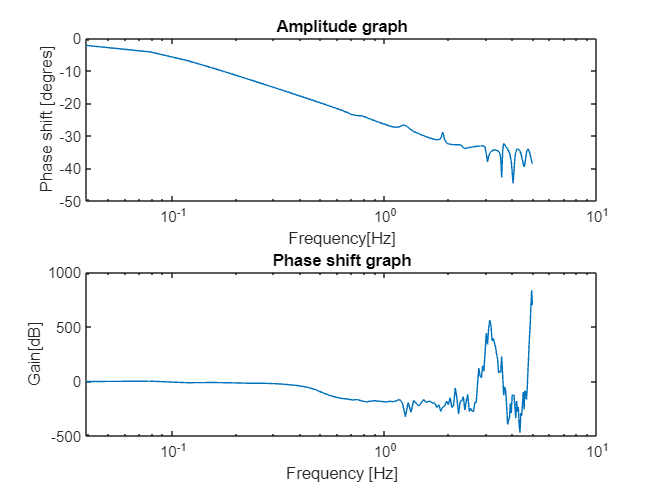

G_jw = FT_proces ./ FT_input;

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Phase shift [degres]")
subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Gain[dB]")

frequencies = [1, 2, 5, 10, 20]; % Example frequencies in Hz
t = 0.1:0.1:25.6

t =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


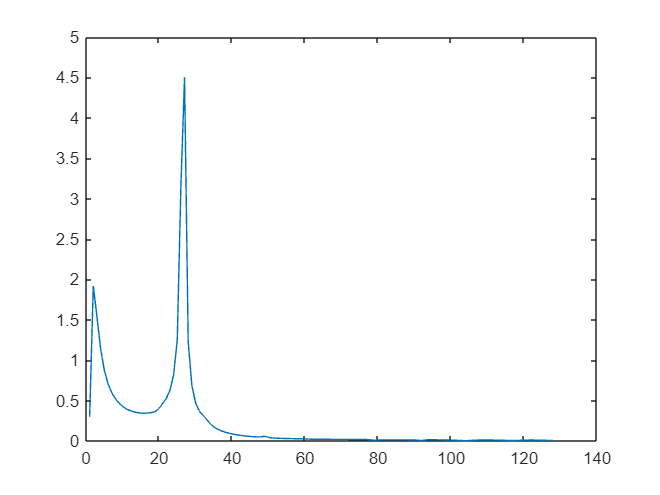

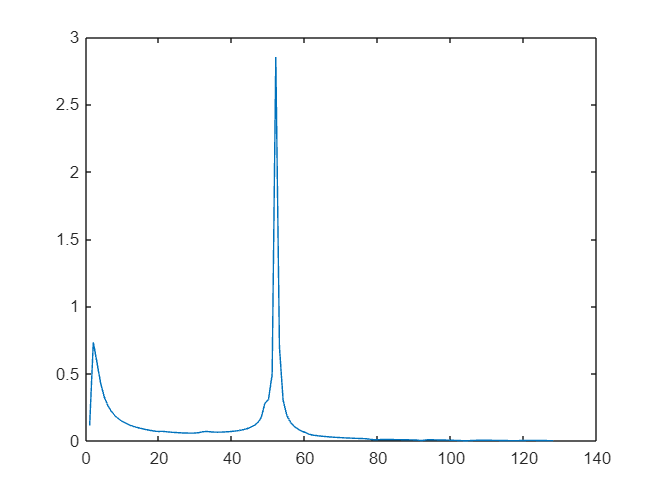

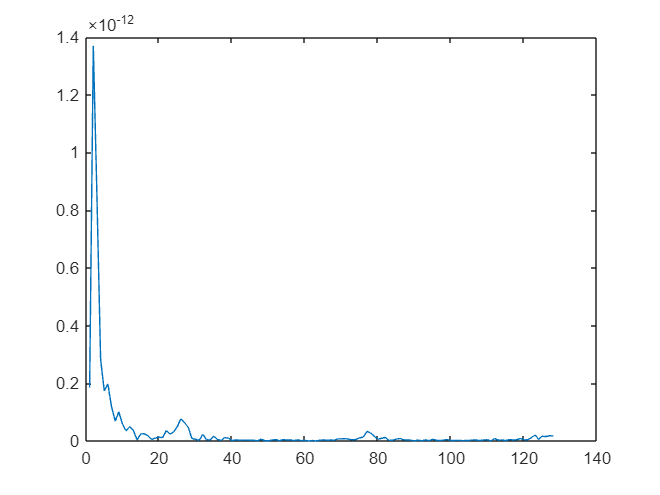

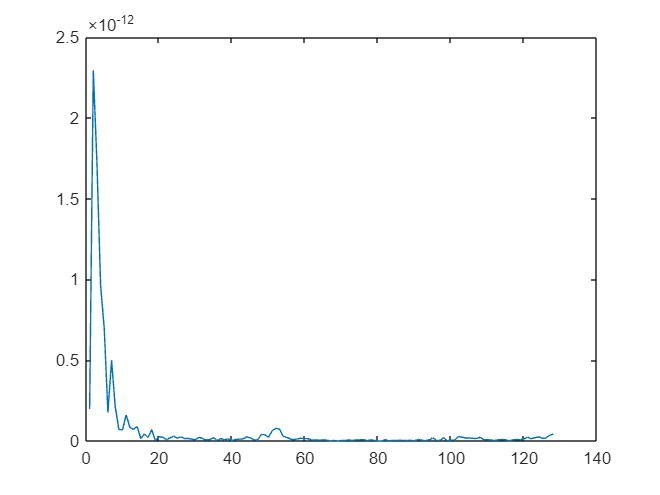

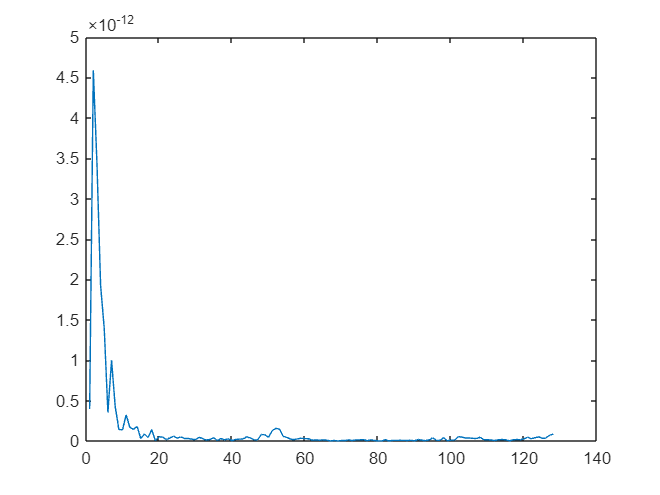

for i = 1:length(frequencies)
    figure
    excitation = sin(2 * pi * frequencies(i) * t);
    output = abs(fft(excitation)) .* abs(G_jw)';
    plot(output(1:end/2))
end

frequencies = 5
excitation = sin(2 * pi * frequencies * t);

% figure
% plot(excitation)
% figure
% plot(abs(fft(excitation)))

output = abs(fft(excitation)) .* abs(G_jw)';

figure
plot(output(1:end/2))
